s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties



wc = 10e3 ;

numerator = 1

numerator = 1


bessel_1 = 1 / ( (s/wc) + 1 )

bessel_1 =
 
    10000
  ---------
  s + 10000
 
Continuous-time transfer function.
Model Properties


bessel_2 = 3 / ( (s/wc)^2 + 3*(s/wc) + 3 )

bessel_2 =
 
            3e12
  -------------------------
  10000 s^2 + 3e08 s + 3e12
 
Continuous-time transfer function.
Model Properties



wn = wc / 1.745 ;
bessel_3 = 15 / ( (s/wn)^3 + 6*(s/wn)^2 + 15*(s/wn) + 15 )

bessel_3 =
 
                       5.313e23
  ---------------------------------------------------
  1.882e11 s^3 + 6.471e15 s^2 + 9.271e19 s + 5.313e23
 
Continuous-time transfer function.
Model Properties


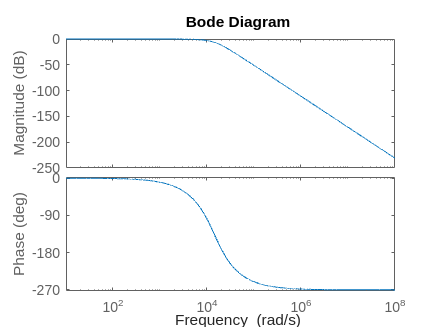


bode(bessel_3, logspace(1, 8, 10e3))


bessel_d = c2d(bessel_3, 1/10e3 ) 

bessel_d =
 
     0.1953 z^2 + 0.3203 z + 0.03468
  -------------------------------------
  z^3 - 0.6378 z^2 + 0.2202 z - 0.03212
 
Sample time: 0.0001 seconds
Discrete-time transfer function.
Model Properties
